# Signaux et Systèmes, Ex3

# Filtres numériques

Clear sound

clear sound;

## Play original

clear sound;
sound(music, Fs);

## 3.1 Filtre non-récursif

clear;clc;close;
% y[n] = b_0*x[n] + b_1*x[n-1] + ... + b_M*x[n-M]

% Charger la musique
% load("music2.mat"); music = music2';
load("music.mat");

% music = music/max(abs(music));
% sound(music, Fs);
clear sound;

b = [0.5; 0.01; 0.01; 0.5];
musicFiltered = filter_no_recursive(music, b);

% sound(musicFiltered, Fs);
disp("Complete !");

Complete !


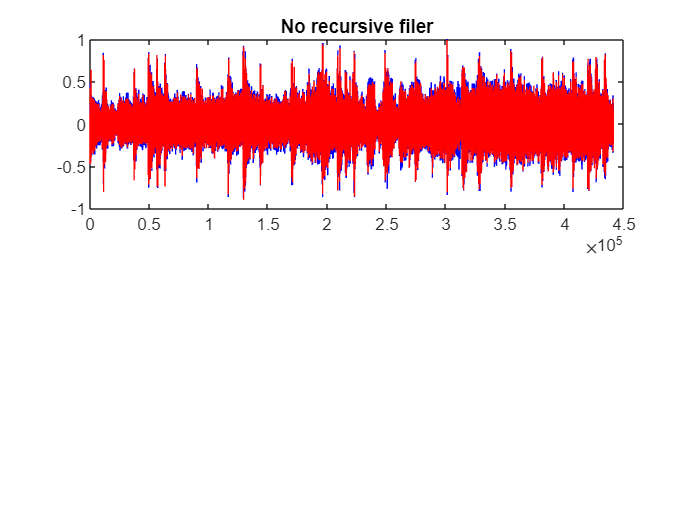


subplot(211);
plot(music, 'b'); hold on;
plot(musicFiltered, 'r');
title("No recursive filer");

## 3.2 Filtre récursif

clear;clc;
% close;
% a_0*y[n] = b_0*x[n] + b_1*x[n-1] + ... + b_M*x[n-M]
%                     - a_1*y[n-1] - ... - a_L*y[n-L]

% Charger la musique
% load("music2.mat"); music = music2';
load("music.mat");
% music = music/max(abs(music));
% sound(music, Fs);
clear sound;

a = [1; -1.8; 0.8];
b = [1; -2; 1];
musicFiltered = filter_recursive(music, a, b);
% Normaliser
% musicFiltered = musicFiltered / max(abs(musicFiltered));

% sound(musicFiltered, Fs);
disp("Complete !");

Complete !


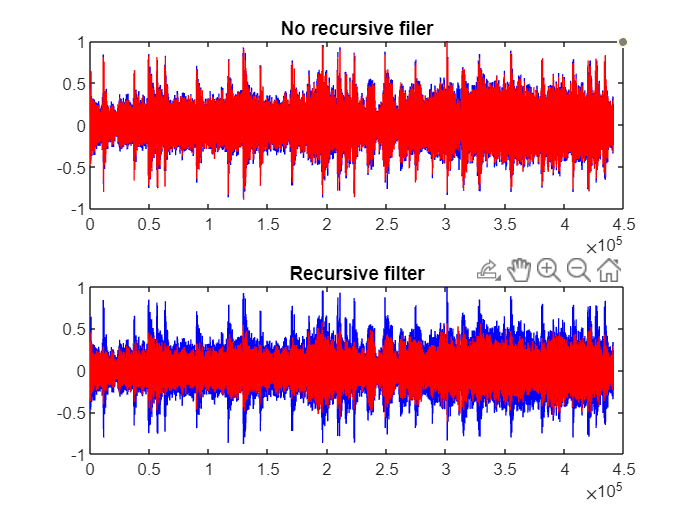


subplot(212);
plot(music, 'b'); hold on;
plot(musicFiltered, 'r');
title("Recursive filter");

## Plot

% plot(music, 'b'); hold on;
% plot(musicFiltered, 'r');


## Ex 3.3 Clean

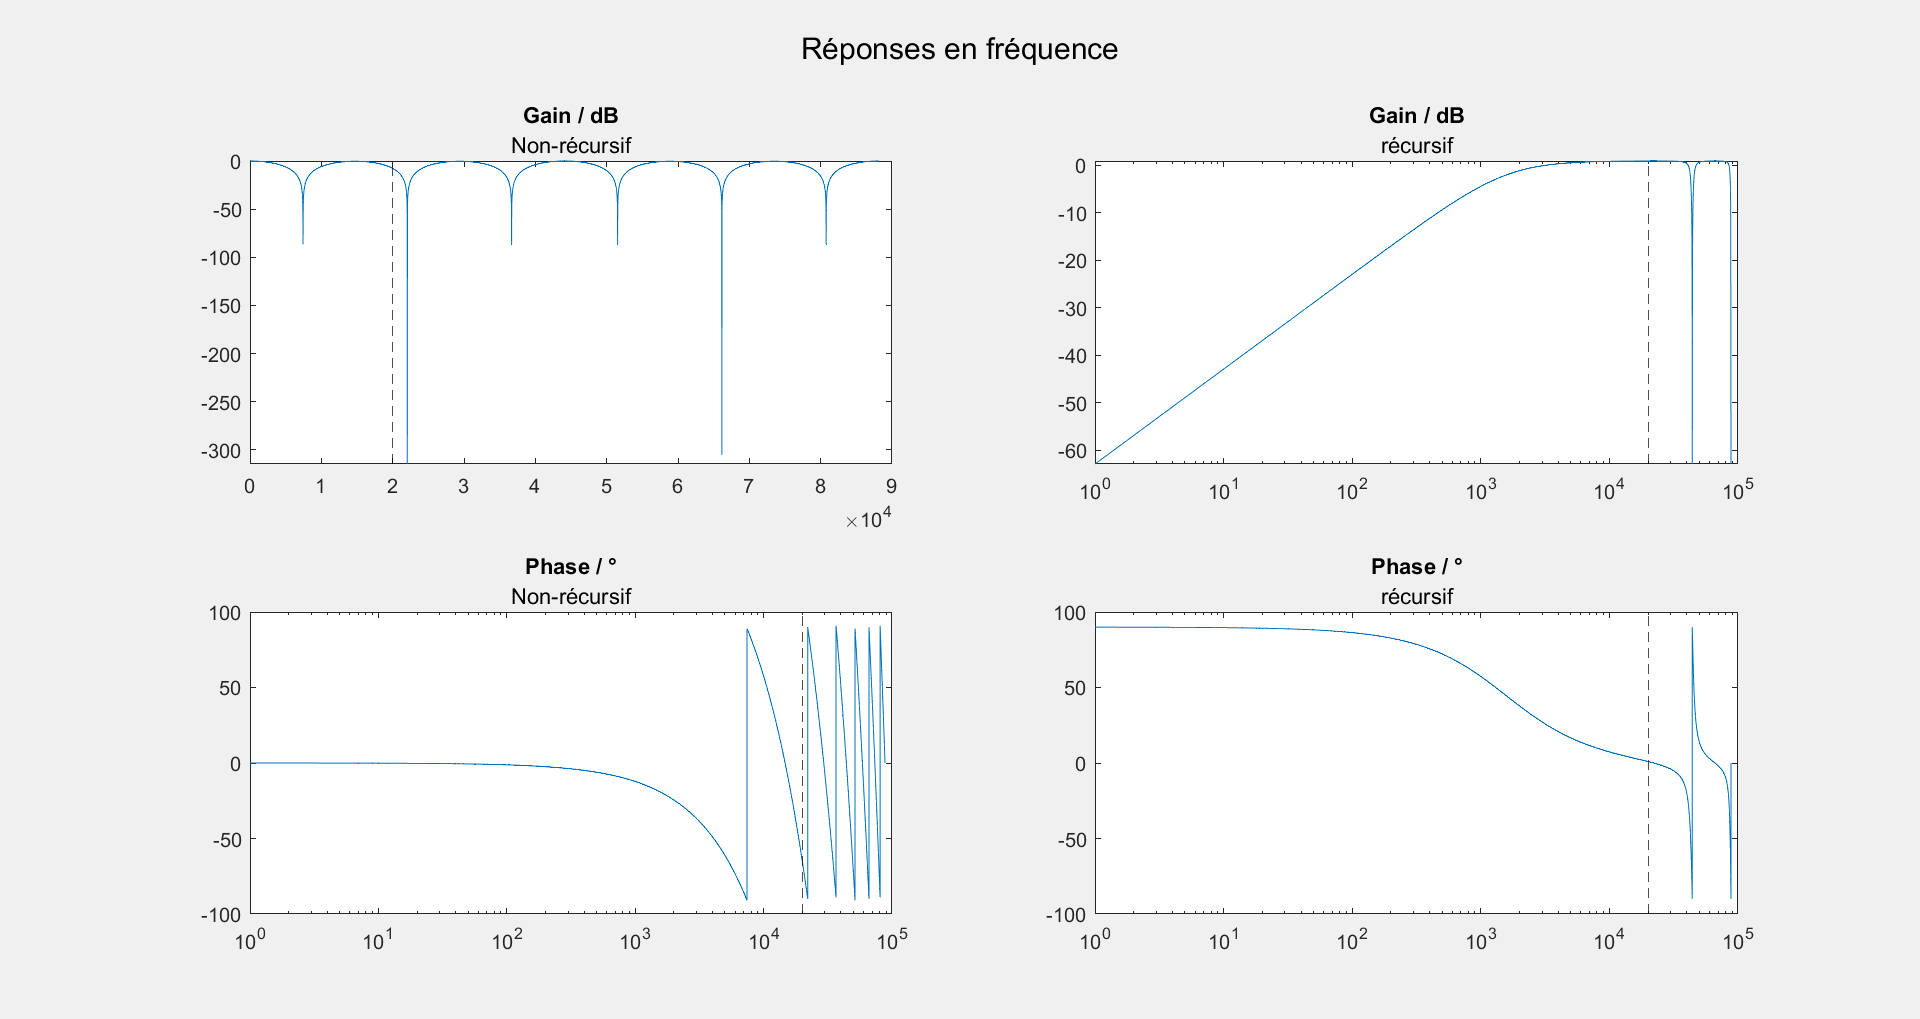

clear;clc;close;

Fs = 44.1e3;
f = 1:2*Fs;
Omega = 2*pi*f/Fs;
% Omega = f;

% Non récursif
% Nous avons un coupe-bande de la fréquence 7431 Hz. (D'autres fréquences
% sont coupées dans la zone non-audible).
H1 = 0.5 + 0.01*exp(-1i*Omega*1) + 0.01*exp(-1i*Omega*2) + 0.5*exp(-1i*Omega*3);
H1_G = abs(H1);
H1_P = rad2deg(angle(H1));

% Récursif
% On a clairement un passe-bas avec quelques fréquences coupées mais dans
% la plage non-audible
H2 = (1 - 2*exp(-1i*Omega*1) + 1*exp(-1i*Omega*2))./(1 - 1.8*exp(-1i*Omega*1) + 0.8*exp(-1i*Omega*2));
H2_G = abs(H2);
H2_P = rad2deg(angle(H2));

% Plot

figure("WindowState","maximized"); % Ouvrir la fenêtre en maximized
set(gcf,'Visible','on'); % Ouvre le plot automatiquement (en live script)
sgtitle("Réponses en fréquence");

subplot(221);
semilogx(f, 20*log10(H1_G));
xline(20e3, 'k--');
title("Gain / dB");
subtitle("Non-récursif");
subplot(223);
semilogx(f, H1_P);
xline(20e3, 'k--');
title("Phase / °");
subtitle("Non-récursif");

subplot(222);
semilogx(f, 20*log10(H2_G));
xline(20e3, 'k--');
title("Gain / dB");
subtitle("récursif");
subplot(224);
semilogx(f, H2_P);
xline(20e3, 'k--');
title("Phase / °");
subtitle("récursif");


% Les fonctions sont périodiques en linéaire
% Pour H(j*Omega), elle sont toujours répétitives


## Ex 3.4

% Les pôles calculés avec l'équation caractéristique sont :
% r1 = -1 et r2 = -0.8

tf = (1)/(1) 

fe = 44.1e3;
figure('name', 'Filtre non récursif');
H_no_rec = tf([1,-2,1], [1 0 0], 1/fe);

Incorrect number or types of inputs or outputs for function 'tf'.

bode(H_no_rec);
grid on;


